# Compound Interest

## Task 1

For a savings account with a 6% annual interest rate, the account balance A(t) after t years solves the differential equation

dAdt=rA  where r=0.06

Task

You open a savings account with an initial deposit of $100. The account has a 6% annual interest rate.

Find the account balance after 10 years, and plot the account balance over the first 10 years the account is open.

To do this, complete the following steps:

- Define the interval `tRange`. 

- Define the initial condition `A0`.

- Define a local ODE function `sixPercentInterest` to implement the ODE.

- Use `ode45` to solve the ODE. Name the outputs `tSol` and `ASol`.

-  Plot `ASol` as a function of `tSol`.

- Find the account balance at the end of 10 years, and assign it to the variable `A10`.

Find and plot the account balance for the first 10 years.

*Remember to define your ODE function at the bottom of this script.*

tRange=[0 10]

tRange =      0    10


A0=100

A0 = 100

[tSol, ASol]=ode45(@sixPercentInterest,tRange,A0)

tSol =          0
    0.2500
    0.5000
    0.7500
    1.0000
    1.2500
    1.5000
    1.7500
    2.0000
    2.2500


ASol =   100.0000
  101.5113
  103.0455
  104.6028
  106.1837
  107.7884
  109.4174
  111.0711
  112.7497
  114.4537


plot(tSol,ASol)
A10=ASol(end)

A10 = 182.2119

## Task 2

Similarly, for an account with a 3% annual interest rate, the account balance A(t) after t years solves the differential equation

dAdt=rA where r=0.03

Task

At the end of 10 years, the annual interest rate on the account is decreased to 3%. 

Find the account balance for years 10 through 20 where the account has a 3% annual interest rate. Add it to your plot of the account balance in  the first 10 years.

To do this, complete the following steps:

- Define a local ODE function `threePercentInterest` to implement the ODE.

- Use `ode45` to solve the ODE over t = 10 to 20 with the initial condition the account balance at 10 years, `A10`.

- Assign the outputs to the variables `tSol2` and `ASol2`.

- Add the plot of `ASol2` against `tSol2` to your existing plot.

Find the account balance for years 10 through 20, and add it to your previous plot

*Remember to define your ODE function at the bottom of this script.*

tRange2=[10 20]

tRange2 =     10    20


A10=10

A10 = 10

[tSol2, ASol2]=ode45(@threePercentInterest,tRange2,A10)

tSol2 =    10.0000
   10.2500
   10.5000
   10.7500
   11.0000
   11.2500
   11.5000
   11.7500
   12.0000
   12.2500


ASol2 =    10.0000
   10.0753
   10.1511
   10.2276
   10.3045
   10.3821
   10.4603
   10.5390
   10.6184
   10.6983


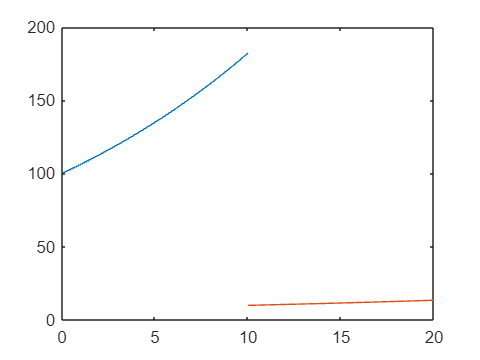

hold on
plot(tSol2,ASol2)
hold off

## Task 1 (continued)

Define the ODE function for 6% interest:      where  

function dAdt=sixPercentInterest(t,A)
r=0.06;
dAdt=r.*A;
end

## Task 2 (continued)

Define the ODE function for 3% interest:      where  

function dAdt=threePercentInterest(t,A)
r=0.03;
dAdt=r.*A;
end